format shortg
clearvars all

# Oppgave 1

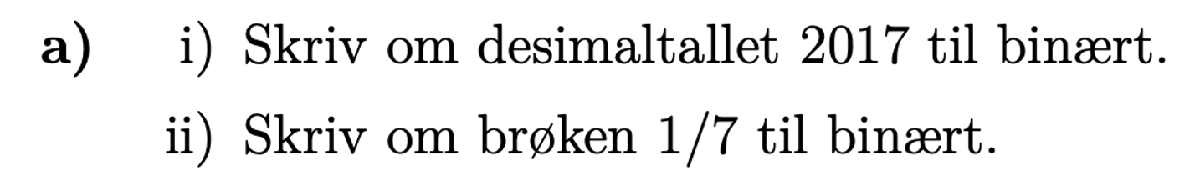

#### (i)

2017-(1024+512+256+128+64+32+1)

ans =      0



$$\begin{array}{l}
{2017}_{10} =1024+512+256+128+64+32+1\\
\;\;\;\;\;\;\;\;\;\;=2^{10} +2^9 +2^8 +2^7 +2^6 +2^5 +2^0 \\
\;\;\;\;\;\;\;\;\;\;={11111100001}_2 
\end{array}$$


#### (ii)


$$\begin{array}{l}
2*\frac{1}{7}=\frac{2}{7}+0\\
2*\frac{2}{7}=\frac{4}{7}+0\\
2*\frac{4}{7}=\frac{1}{7}+1
\end{array}$$



$${\frac{1}{7}}_{10} =0\ldotp {\bar{001} }_2$$


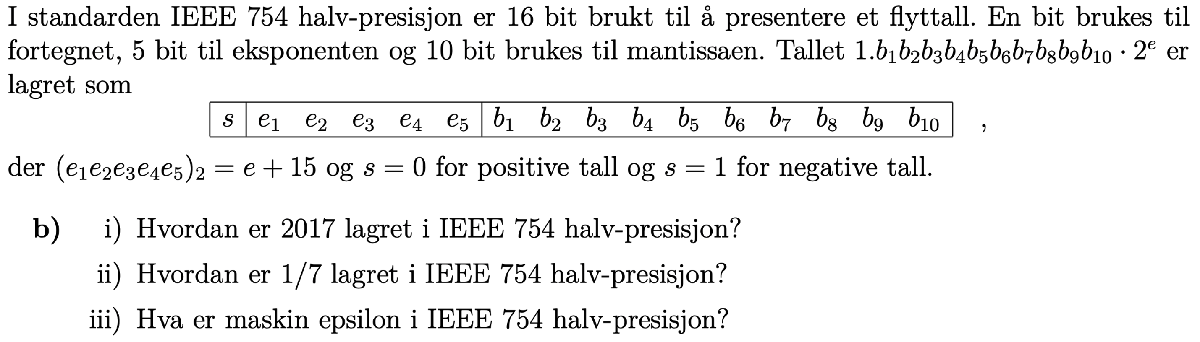

#### (i)

skriver først om til "normalform"


$$2017={11111100001}_2 ={1\ldotp 1111100001}_2 *2^{10}$$



$${\left(-1\right)}^s *2^{e+15} *\left(1+\frac{m}{2^{10} }\right)$$



$$s=0,e=10+15=25,m=1111100001$$



$$0\;\left|\;11001\;\right|\;1111100001$$


#### (ii)

skriver først om til "normalform"


$$\frac{1}{7}={0\ldotp \bar{001} }_2 ={1\ldotp \bar{001} }_2 *2^{-3}$$



$$s=0,e=-3+15=12,m=0010010010$$



$$0\;\left|\;01100\;\right|\;0010010010$$


#### (iii)


$$e_{\textrm{mach}} =\frac{1}{2^{10} }$$


2^-10

ans =    0.00097656


# Oppgave 2

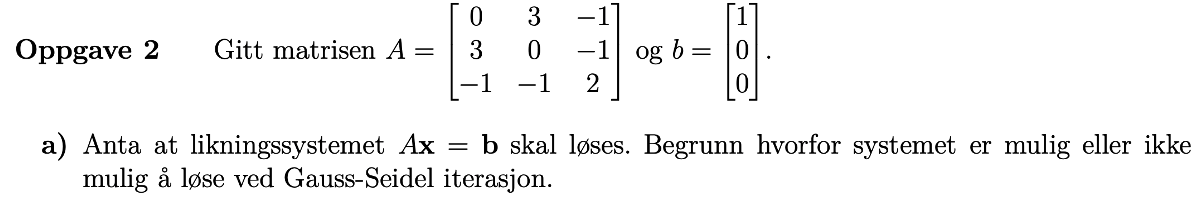

Likningssystemet kan løses med Gauss-Seidel, men da må vi først endre rekkefølgen på radene slik at matrisen A blir diagonal dominant:


$$\textrm{PA}=\left\lbrack \begin{array}{ccc}
1 & 0 & 0\\
0 & 1 & 0\\
0 & 0 & 1
\end{array}\right\rbrack \left\lbrack \begin{array}{ccc}
0 & 3 & -1\\
3 & 0 & -1\\
-1 & -1 & 2
\end{array}\right\rbrack =\left\lbrack \begin{array}{ccc}
0 & 1 & 0\\
1 & 0 & 0\\
0 & 0 & 1
\end{array}\right\rbrack \left\lbrack \begin{array}{ccc}
3 & 0 & -1\\
0 & 3 & -1\\
-1 & -1 & 2
\end{array}\right\rbrack$$


Men matrisen er allikevel ikke strengt diagonal dominent da vi i tredje rad har at $a_{33} =a_{31} +a_{32} =2$

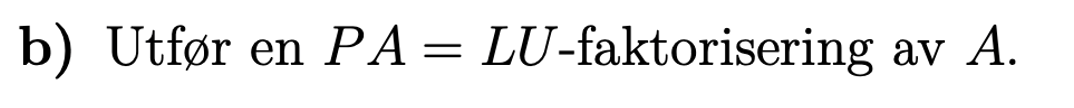


$$\begin{array}{l}
\textrm{PA}=\left\lbrack \begin{array}{ccc}
0 & 1 & 0\\
1 & 0 & 0\\
0 & 0 & 1
\end{array}\right\rbrack \left\lbrack \begin{array}{ccc}
3 & 0 & -1\\
0 & 3 & -1\\
-1 & -1 & 2
\end{array}\right\rbrack \\
\textrm{LU}=\left\lbrack \begin{array}{ccc}
1 & 0 & 0\\
0 & 1 & 0\\
0 & 0 & 1
\end{array}\right\rbrack \left\lbrack \begin{array}{ccc}
3 & 0 & -1\\
0 & 3 & -1\\
-1 & -1 & 2
\end{array}\right\rbrack \Rightarrow \left\lbrack \begin{array}{ccc}
1 & 0 & 0\\
0 & 1 & 0\\
-1/3 & 0 & 1
\end{array}\right\rbrack \left\lbrack \begin{array}{ccc}
3 & 0 & -1\\
0 & 3 & -1\\
0 & -1 & 5/3
\end{array}\right\rbrack \Rightarrow \left\lbrack \begin{array}{ccc}
1 & 0 & 0\\
0 & 1 & 0\\
-1/3 & -1/3 & 1
\end{array}\right\rbrack \left\lbrack \begin{array}{ccc}
3 & 0 & -1\\
0 & 3 & -1\\
0 & 0 & 4/3
\end{array}\right\rbrack 
\end{array}$$



$$\left\lbrack \begin{array}{ccc}
0 & 1 & 0\\
1 & 0 & 0\\
0 & 0 & 1
\end{array}\right\rbrack \left\lbrack \begin{array}{ccc}
3 & 0 & -1\\
0 & 3 & -1\\
-1 & -1 & 2
\end{array}\right\rbrack =\left\lbrack \begin{array}{ccc}
1 & 0 & 0\\
0 & 1 & 0\\
-1/3 & -1/3 & 1
\end{array}\right\rbrack \left\lbrack \begin{array}{ccc}
3 & 0 & -1\\
0 & 3 & -1\\
0 & 0 & 4/3
\end{array}\right\rbrack$$


    
$$\mathrm{Ax}=b\Rightarrow \mathrm{PAx}=\mathrm{Pb}\Rightarrow \mathrm{LUx}=\mathrm{Pb}$$


løser først $\textrm{Lc}=\textrm{Pb}$


$$\begin{array}{l}
\left\lbrack \begin{array}{ccc}
1 & 0 & 0\\
0 & 1 & 0\\
-1/3 & -1/3 & 1
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
c_1 \\
c_2 \\
c_3 
\end{array}\right\rbrack =\left\lbrack \begin{array}{ccc}
0 & 1 & 0\\
1 & 0 & 0\\
0 & 0 & 1
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
1\\
0\\
0
\end{array}\right\rbrack \\
\left\lbrack \begin{array}{c}
c_1 \\
c_2 \\
c_3 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
0\\
1\\
1/3
\end{array}\right\rbrack 
\end{array}$$


Og deretter $\textrm{Ux}=c$


$$\begin{array}{l}
\left\lbrack \begin{array}{ccc}
3 & 0 & -1\\
0 & 3 & -1\\
0 & 0 & 4/3
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
x_1 \\
x_2 \\
x_3 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
0\\
1\\
1/3
\end{array}\right\rbrack \\
\left\lbrack \begin{array}{c}
x_1 \\
x_2 \\
x_3 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
\left(0+x_3 \right)/3\\
\left(1+x_3 \right)/3\\
\frac{1/3}{4/3}
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
\left(1/4\right)/3\\
\left(1+1/4\right)/3\\
1/4
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
1/12\\
5/12\\
1/4
\end{array}\right\rbrack 
\end{array}$$


# Oppgave 5

#### b)

A = [0 1 2 3]';
DFT = 1/sqrt(4)*fft(A)

DFT =             3 +          0i
           -1 +          1i
           -1 +          0i
           -1 -          1i


#### c)